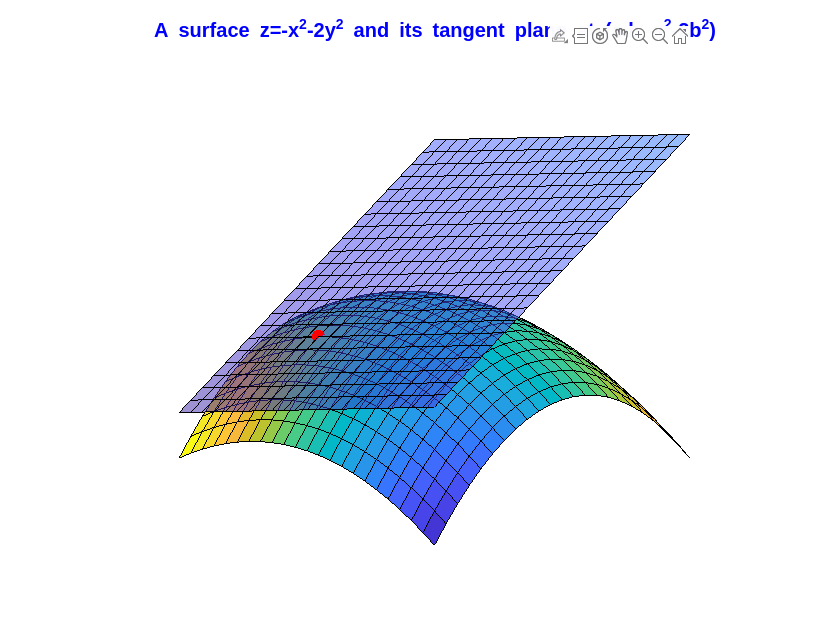

l=-1.1:0.1:1.1; 
m=-1.1:0.1:1.1;
[u,v]=meshgrid(l,m);
x=u;
y=v;
z=-u.^2-2*v.^2;
C1=10*x.*y+10;

a =-0.5;
b =-0.5;

w=a^2+2*b^2-2*a*x-4*b*y;
X=[a];
Y=[b];
Z=[-a^2-2*b^2];

surf(x,y,z,C1);
axis off
xlim([-1.1 1.1])
ylim([-1.1 1.1])
view(45,20)
pbaspect([1 1 1])
title('A surface z=-x^2-2y^2 and its tangent plane at (a,b,-a^2-2b^2)','Color','blue','FontSize',10)
hold on 
surf(x,y,w,'FaceAlpha',0.5);
scatter3(X,Y,Z,'filled','MarkerEdgeColor','red','MarkerFaceColor','red');
hold off

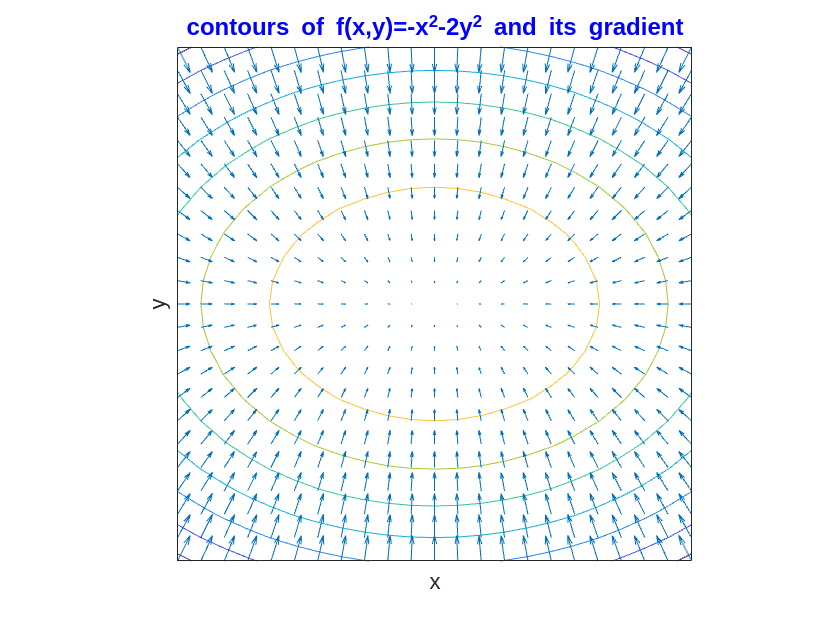

X=-2*x; Y=-4*y;

contour(x,y,z)
title('contours of f(x,y)=-x^2-2y^2 and its gradient','Color','blue','FontSize',12)
xlabel('x')
xticks([])
ylabel('y')
yticks([])
pbaspect([1 1 1])  
hold on
quiver(x,y,X,Y);
hold off

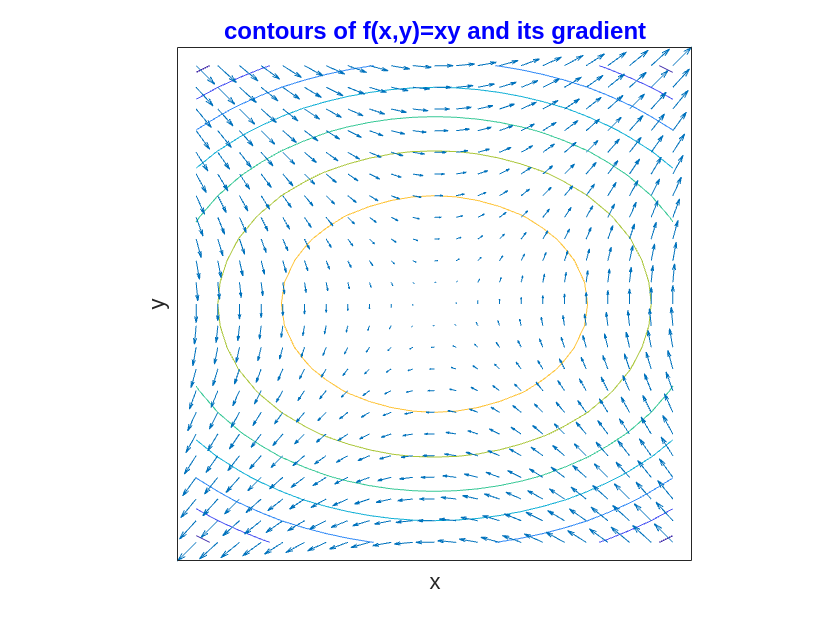

X1=y; Y1=x;

contour(x,y,z)
title('contours of f(x,y)=xy and its gradient','Color','blue','FontSize',12)
xlabel('x')
xticks([])
ylabel('y')
yticks([])
pbaspect([1 1 1])  
hold on
quiver(x,y,X1,Y1);
hold off